## **平均と分散・標準偏差**

データをたくさん集めてもそのままではただの数字の集まりにすぎません．何らかの方法でデータの特徴をとらえ，説明できる形にすることで，データから見えてくるものがでてきます．

ここで扱うデータは，宇宙をテーマとした話と異なりますが，平均，分散，標準偏差といった，統計を行う上で非常に重要な概念について説明しますので，概念を理解しましょう！

学校での理科のテストを題材にします．下記が，1組，2組 クラス 10人のテストの点数のデータです．

score_class1 = [ 74   100    99    85    94    74    83    98    94    99]

score_class1 =     74   100    99    85    94    74    83    98    94    99


score_class2 = [ 87    80    89    90    87    88    88    84    87    81]

score_class2 =     87    80    89    90    87    88    88    84    87    81


各クラスのテスト結果を可視化してみると，下記のようになります．

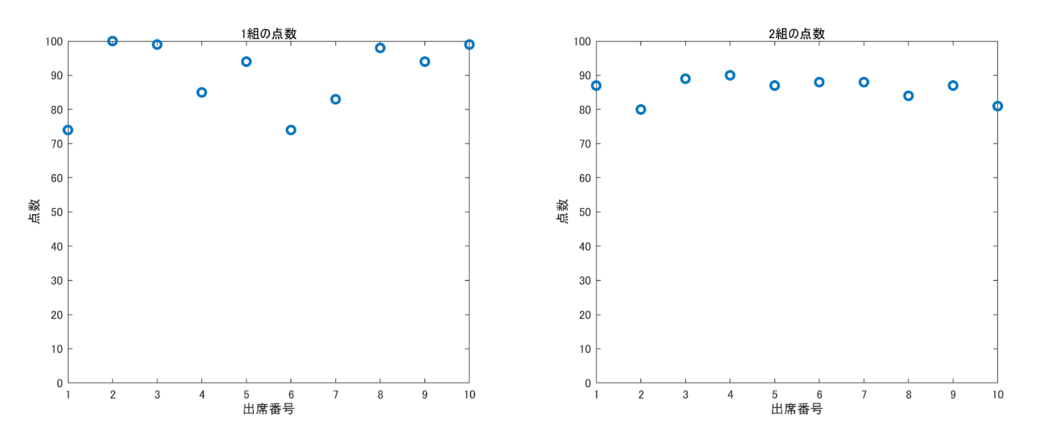

1組と2組で，どちらのクラスの方がより多くの点数をとったでしょうか．また，どちらのクラスが，点数のバラつきがありそうですか？

データを見ただけでは，答えがでない場合もあるかと思います．そんな時に利用できるのが，平均・分散・標準偏差の概念です．

まずは，平均から説明します．**平均**とは，複数個のデータすべてを足し合わせて，それをデータ数で割った値です．データの値が，一般にどの程度かを表す代表の値を計算することができます．数式で表すと以下のようになります．


$$\bar{x} =\frac{1}{n}\left(x_1 +x_2 +\cdots +x_n \right)$$


MATLAB では，平均を求める関数として， mean が用意されています．

参考：[`mean`](matlab:doc('mean'))

その特徴を調べるために各クラスの平均値を求めると，以下の結果となります．

mean_c1 = mean(score_class1)

mean_c1 = 90

mean_c2 = mean(score_class2)

mean_c2 = 86.1000

1組は悪い点の人がいるため，一見クラス全体で点数が悪そうにも思えますが，逆に高得点の人もいて全体の点数を押し上げています．

`mean` 関数を実行した結果，理科のテストの平均点は，わずかですが 1組の方が高いことが分かります．

下記に，各クラスのテスト結果に，平均点をプロットしました．

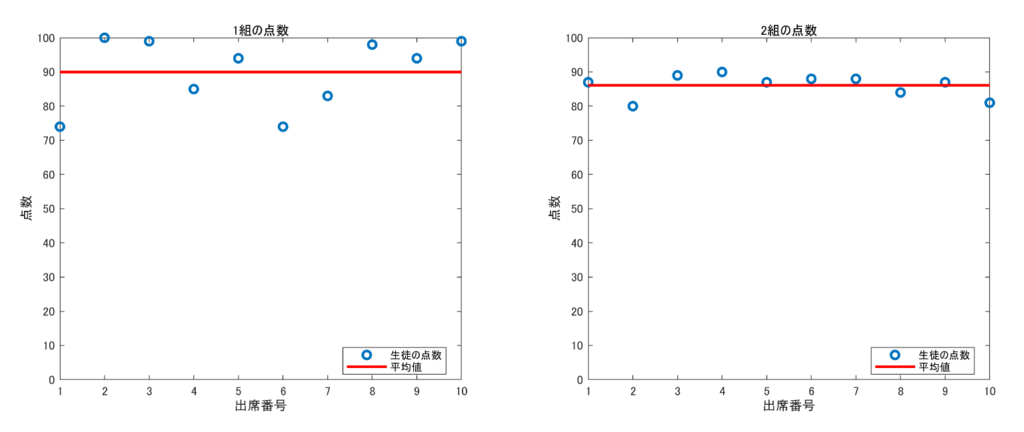

次に，分散と標準偏差について説明します．

**分散**とは，各データと平均との差を計算し，その2乗をすべて足し合わせてデータ数で割った値です．データのばらつき具合を表す指標です．下記の式で定義されています．


$$v=\frac{1}{n}\left\lbrace {\left(x_1 -\bar{x} \right)}^2 +{\left(x_2 -\bar{x} \right)}^2 +\cdots +{\left(x_n -\bar{x} \right)}^2 \right\rbrace$$


**標準偏差**とは，平均と単位を合わせるために分散の平方根をとったものです．単位をそろえることで，データのばらつきがわかりやすくなります．


$$s=\sqrt{v}$$


分散と標準偏差を求めるには，それぞれ var 関数，std 関数を使用します．

参考：[`var`](matlab:doc('var'))，[`std`](matlab:doc('std'))

**■ 分散**

var_c1 = var(score_class1,1)

var_c1 = 94.4000

var_c2 = var(score_class2,1)

var_c2 = 10.0900

1組の方が，分散が大きいですね．次に，標準偏差を求めてみましょう．

**■ 標準偏差**

std_c1 = std(score_class1,1)

std_c1 = 9.7160

std_c2 = std(score_class2,1)

std_c2 = 3.1765

標準偏差も，1組の方が大きいですね．

標準偏差は，データのバラつき度を表現しますが，他の見方をすることもできます．それを理解するために，各クラスの生徒の定数とともに，平均値と，平均値 ± 標準偏差 の線を引いてみると，下記のようなグラフになります．

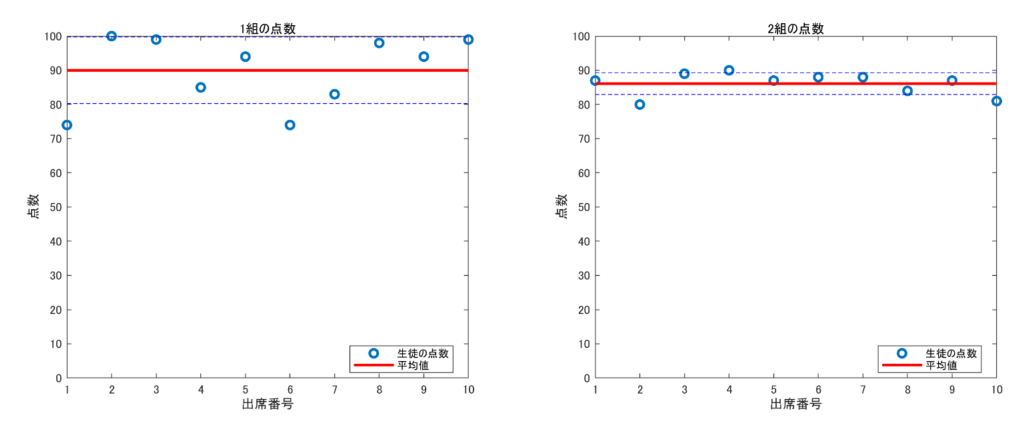

どちらのグラフともに，**約70%のデータ**が **平均値 ± 標準偏差** の間に含まれます．グラフで見ると，2組の方がバラつきが少ないことが確認できますね．

分散や標準偏差が小さいほど，青い点線間の距離が小さくなり，バラツキが少ないデータであることが分かります．

平均と標準偏差でどのようなことが分かるか，イメージはわきましたか？

では，Mission に戻って，実際に平均と標準偏差を求めて，結果を考察してみましょう！

[Mission3に戻る](matlab:closeAndMove("sbda_mission3.mlx"))

Copyright 2020 - 2022 The MathWorks, Inc.